## Aeromechanics of Unmanned Aerial Systems

## Homework 4

Due: 17/11/2025 

#### Student Details:

Name: Md Tahseen Aslam                        Roll No: 251010069                 Dept: AE-UAS(Autonomy)

Email: tahseenaslam25@iitk.ac.in            Mobile No: +91-8001156771

## Q1. 

Relevant data pertaining to an unmanned helicopter are given below: 

- Density of air, ρ 1.225 kg/m3 

- Number of blades, Nb = 2

- Blade radius, R 1 m 

- Blade chord, c 0.09 m 

- Profile Drag coefficient, Cdo 0.01 

- Lift curve slope, Clα 5.73 

- Rotor angular rate, Ω 150 rad/sec 

- Hover Thrust T 300 N 

- Root cutout 20% of R 

Consider blade twist for four different configurations: 

    (i) ideal twist with θtip, 

    (ii) θtw of 0◦ , 

    (iii) θtw of -15◦ (linear), and 

    (iv) ideal twist with θtip and ideal taper (assume ctip = 0.5c). 

Assuming non-uniform inflow (BEMT without tip loss), evaluate the following and show each item in one figure for the helicopter in hovering flight: 

(a) Find out the reference pitch input θtip or θ75 for hovering flight and plot the variation of pitch angle with non-dimensional radial location (all 4 twist cases in one figure). In a separate plot, compare the numerical solution obtained for ideal twist with the closed form exact formula derived in class. (15) 

(b) Variation of angle of attack with non-dimensional radial location (all 4 twist cases in one figure). (5) 

(c) Variation of induced inflow with non-dimensional radial location (all 4 twist cases in one figure). (5) 

(d) Variation of thrust distribution (i.e. dCT /dr), total torque (CQ) distribution, induced torque distribution (CQi ) and profile torque (CQp ) with non-dimensional radial loca�tion (all 4 twist cases in one figure each). (15) 

Report your observations for each of the figures. Make sure you use legends and different line types to allow identification of each graph.

## Solution:

### Algorithm Used for Solving Q1:

#### **Step 1:** The "Outer Loop" (Root-Finding)

finds the reference_pitch which satisfies the equation:

**calculate_total_thrust(reference_pitch) - 300 = 0**

- Guess a reference_pitch (e.g., 8°).

- Call the Inner Loop (Step 2) to get the Total_Thrust for this guess.

- Check:

**If Total_Thrust ≈ 300 N: You are done. The reference_pitch is correct.**

**If Total_Thrust < 300 N: Increase your guess and repeat from Step 2.**

#### **If Total_Thrust > 300 N: Decrease your guess and repeat from Step 2.**

#### **Step 2:** The "Inner Loop" (BEMT + Gaussian Quadrature)

This function, calculate_total_thrust(reference_pitch), calculates the total thrust for a given pitch.

**1. Discretize Blade into Elements:**

- Divide the blade span from the root cutout (a = 0.2R) to the tip (b = R) into M = 10 equal elements. 

- The k-th element spans from r_k to r_{k+1}.

- Initialize Total_Thrust = 0.

**2. Loop Over Elements (k from 1 to M):**

- Get the start (a_k) and end (b_k) radius for the current element.

- Initialize Element_Thrust = 0.

- Loop j from i to vi (Gaussian Quadrature):

**i. Get Quadrature Point:**

- Get the 6-point Gaussian weight w_j and abscissa y_j.

**ii. Map Abscissa to Radius:**

- Convert the y_j (which is on [–1, 1]) to the physical radius r_j within the element [a_k, b_k]:

**iii. Get Local Properties:**

- At this specific point r_j:

- Calculate non-dimensional radius: $x_j =\frac{r_j }{R}$

- Calculate local pitch θ_j (using reference_pitch and the formula for the specific configuration).

- Calculate local chord c_j.

**iv. Solve for Local Inflow (λ_j):**

- Solve the BEMT quadratic equation at this single point x_j to find the local non-dimensional inflow λ_j:


$${4\ldotp x_j \ldotp \lambda^2 }_j \left(x\right)+\frac{1}{2}\sigma_j {\ldotp c}_{l\alpha } \ldotp x_j \ldotp \lambda_j -\frac{1}{2}\sigma_j {\ldotp c}_{l\alpha } \ldotp {x^2 }_j \ldotp \theta_j =0$$


**v. Calculate Local C_l:**


$$c_{l,j} =c_{l\alpha } \;\left(\theta_j -\frac{\lambda_j }{x_j }\right)\;$$


**vi. Calculate Thrust Integrand f(r_j) (using BET):**

- The thrust integrand from Blade Element Theory is:


$$f(r_j )=\frac{dT}{dr}{\left|\right.}_{r_j } =\frac{1}{2}\rho N_b (\Omega R)^2 \cdot c(x_j )\cdot x_j^2 \cdot C_{l,j}$$


**vii. Add to Element Sum:**


$$\textrm{Element}\_\textrm{Thrust}=\textrm{Element}\_\textrm{Thrust}+w_j *f\left(r_j \right)$$


**3. Scale Element and Add to Total:**

- After the inner 6-point loop, scale the result by the change of variable factor.

- Add this element's thrust to the total: **Total_Thrust** = **Total_Thrust** + **Element_Thrust**

**4. Return:**

- After looping through all $M=10$ elements, return **Total_Thrust**.

### Q1 - PART - A

% PARAMETERS, GAUSS-6 DATA

rho = 1.225;        % kg/m^3
Nb  = 2;            % number of blades
R   = 1.0;          % m (blade radius)
c_root = 0.09;      % m (root chord, for constant-chord cases)
Cd0 = 0.01;         % profile drag coefficient (not used in part a)
Cl_alpha = 5.73;    % per radian
Omega = 150;        % rad/s
T_req = 300;        % Required thrust (N)
x_root = 0.2;       % nondimensional root cutout (r/R)

% integration setup 
M = 10;                 % number of blade elements

a_global = x_root * R;  % start radius (m)
b_global = R;           % end radius (m)


r_edges = linspace(a_global, b_global, M+1);  

% Standard values:
y_gauss = [ ...
   -0.932469514203152; -0.661209386466265; -0.238619186083197; ...
    0.238619186083197;  0.661209386466265;  0.932469514203152];
w_gauss = [ ...
    0.171324492379170; 0.360761573048139; 0.467913934572691; ...
    0.467913934572691; 0.360761573048139; 0.171324492379170];

A = pi * R^2;
ref_scale = rho * A * (Omega*R)^2;   % so T = C_T * ref_scale

fprintf('Using M = %d elements, 6-point Gauss per element.\n', M);

Using M = 10 elements, 6-point Gauss per element.



% chord function (input: x = r/R)
c_of_x = @(x) c_root * ones(size(x)); 

% chord for tapered case 
c_tip_factor = 0.5;
c_tip = c_root * c_tip_factor;
c_taper = @(x) ( c_root + (c_tip - c_root) .* ((x - x_root) ./ (1 - x_root)) );

% 1) "ideal" 
ideal_theta = @(theta_tip, xvec) min( deg2rad(40), theta_tip ./ (xvec) );  

% 2) "no" twist: constant pitch = theta_tip
no_twist_theta = @(theta_tip, xvec) theta_tip * ones(size(xvec));

% 3) "linear" twist: total -15 deg across span (root minus tip = +15 deg)
total_twist_deg = -15;      
total_twist_rad = deg2rad(total_twist_deg);

theta_root_offset = -total_twist_rad;    
linear_twist_theta = @(theta_tip, xvec) ...
    ( theta_tip + theta_root_offset .* ( (xvec - 1) ./ (x_root - 1) ) );

% 4) "ideal_taper":
ideal_taper_theta = @(theta_tip, xvec) ideal_theta(theta_tip, xvec); 

% function to return chord vector for case
chord_for_case = @(case_id, xvec) ...
    ( strcmp(case_id,'ideal_taper') .* c_taper(xvec) + ...
      (~strcmp(case_id,'ideal_taper')) .* c_of_x(xvec) );


%% INNER LOOP: compute_total_thrust(reference_pitch, case_id)

function T_total = compute_total_thrust_theta(theta_tip, case_id)
    R_ws         = evalin('base','R');
    Nb_ws        = evalin('base','Nb');
    Omega_ws     = evalin('base','Omega');
    Cl_alpha_ws  = evalin('base','Cl_alpha');
    rho_ws       = evalin('base','rho');
    r_edges_ws   = evalin('base','r_edges');
    y_gauss_ws   = evalin('base','y_gauss');
    w_gauss_ws   = evalin('base','w_gauss');
    M_ws         = evalin('base','M');
    fh_ideal      = evalin('base','ideal_theta');
    fh_no         = evalin('base','no_twist_theta');
    fh_linear     = evalin('base','linear_twist_theta');
    fh_ideal_taper= evalin('base','ideal_taper_theta');
    fh_c_of_x     = evalin('base','c_of_x');
    fh_c_taper    = evalin('base','c_taper');

    % total thrust accumulator
    T_total = 0.0;

    % Loop over elements
    for k = 1:M_ws
        a_k = r_edges_ws(k);     % element start (m)
        b_k = r_edges_ws(k+1);   % element end (m)
        elem_sum = 0.0;          % Gaussian sum for this element 
        half_len = (b_k - a_k) / 2;
        mid_pt = (b_k + a_k) / 2;

        for j = 1:6
            yj = y_gauss_ws(j);
            wj = w_gauss_ws(j);
            % Map to physical radius r_j
            r_j = half_len * yj + mid_pt;        % in meters
            x_j = r_j / R_ws;                    % nondim radius

            % get chord and theta at this x_j depending on case
            switch case_id
                case 'ideal'
                    theta_j = fh_ideal(theta_tip, x_j);
                    c_j = fh_c_of_x(x_j);
                case 'no'
                    theta_j = fh_no(theta_tip, x_j);
                    c_j = fh_c_of_x(x_j);
                case 'linear'
                    theta_j = fh_linear(theta_tip, x_j);
                    c_j = fh_c_of_x(x_j);
                case 'ideal_taper'
                    theta_j = fh_ideal_taper(theta_tip, x_j);
                    c_j = fh_c_taper(x_j);
                otherwise
                    error('Unknown case_id in compute_total_thrust_theta');
            end

            
            theta_j = theta_j(:); theta_j = theta_j(1);
            c_j = c_j(:); c_j = c_j(1);

Case ideal: theta_tip = 4.9532 deg   -> produced thrust = 300.000002 N
Case no: theta_tip = 7.1065 deg   -> produced thrust = 299.999699 N
Case linear: theta_tip = 2.5573 deg   -> produced thrust = 299.999872 N
Case ideal_taper: theta_tip = 6.0886 deg   -> produced thrust = 300.000018 N



            % Compute sigma_j (local solidity)
            sigma_j = Nb_ws * c_j / (pi * R_ws);

            % Coefficients for quadratic A*lambda^2 + B*lambda - C = 0
            A = 4 * x_j;
            B = 0.5 * sigma_j * Cl_alpha_ws * x_j;
            C = 0.5 * sigma_j * Cl_alpha_ws * x_j^2 * theta_j;

            % Solve quadratic for lambda_j
            discr = B^2 + 4*A*C;
            if discr < 0
                lambda_j = 0;
            else
                lambda_j = ( -B + sqrt(discr) ) / (2*A);
                if lambda_j < 0
                    lambda_j = ( -B - sqrt(discr) ) / (2*A);
                end
            end

            % local Cl at this point
            Cl_j = Cl_alpha_ws * ( theta_j - (lambda_j / x_j) );

            % local thrust integrand f(r) = dT/dr = 1/2 * rho * Nb * (Omega * r)^2 * c(x) * Cl
            f_rj = 0.5 * rho_ws * Nb_ws * (Omega_ws * r_j)^2 * c_j * Cl_j;

            % accumulate weighted contribution
            elem_sum = elem_sum + wj * f_rj;
        end

       
        Element_Thrust = elem_sum * half_len;

        % add element's thrust to total
        T_total = T_total + Element_Thrust;
    end
end



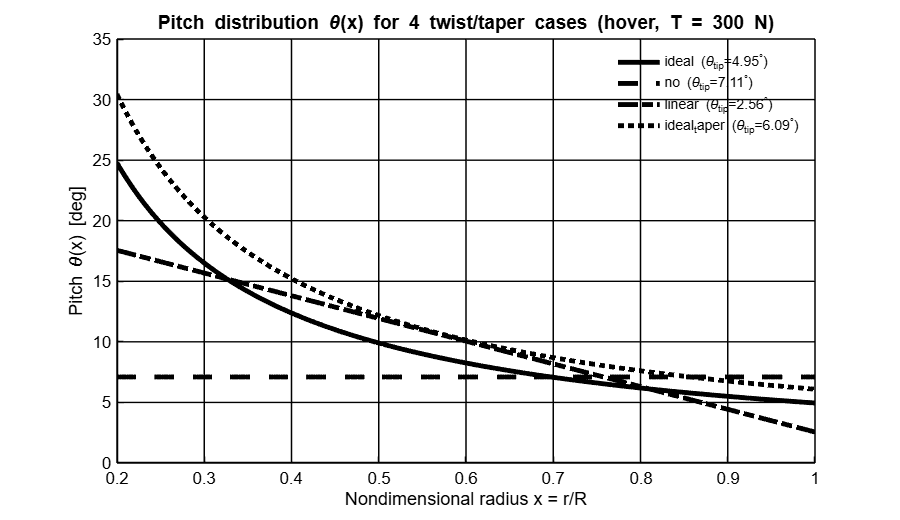

%% OUTER LOOP: find theta_tip for each case
cases = {'ideal','no','linear','ideal_taper'};

theta_tip_solution = zeros(size(cases));
x_plot = linspace(x_root, 1, 300)';   
theta_profiles_deg = zeros(length(x_plot), length(cases));


opts = optimset('TolX',1e-6,'Display','off');


theta_lo = deg2rad(2);
theta_hi = deg2rad(40);

for idx = 1:length(cases)
    case_id = cases{idx};

   
    objfun = @(th) compute_total_thrust_theta(th, case_id) - evalin('base','T_req');

   
    try
        theta_sol = fzero(objfun, [theta_lo theta_hi], opts);
    catch
       
        fprintf('fzero failed for case %s, falling back to grid search + fminsearch...\n', case_id);
        thetas_grid = linspace(theta_lo, theta_hi, 200);
        errs = arrayfun(objfun, thetas_grid);
        [~, ind] = min(abs(errs));
        theta_guess = thetas_grid(ind);
        theta_sol = fminsearch(@(t) abs(objfun(t)), theta_guess, optimset('TolX',1e-6,'Display','off'));
    end

    theta_tip_solution(idx) = theta_sol;

   
    fh_ideal      = evalin('base','ideal_theta');
    fh_no         = evalin('base','no_twist_theta');
    fh_linear     = evalin('base','linear_twist_theta');
    fh_ideal_taper= evalin('base','ideal_taper_theta');

    switch case_id
        case 'ideal'
            theta_vec = fh_ideal(theta_sol, x_plot);
        case 'no'
            theta_vec = fh_no(theta_sol, x_plot);
        case 'linear'
            theta_vec = fh_linear(theta_sol, x_plot);
        case 'ideal_taper'
            theta_vec = fh_ideal_taper(theta_sol, x_plot);
        otherwise
            theta_vec = zeros(size(x_plot));
    end

    theta_profiles_deg(:, idx) = rad2deg(theta_vec(:));
    fprintf('Case %s: theta_tip = %.4f deg   -> produced thrust = %.6f N\n', ...
        case_id, rad2deg(theta_sol), compute_total_thrust_theta(theta_sol, case_id));
end

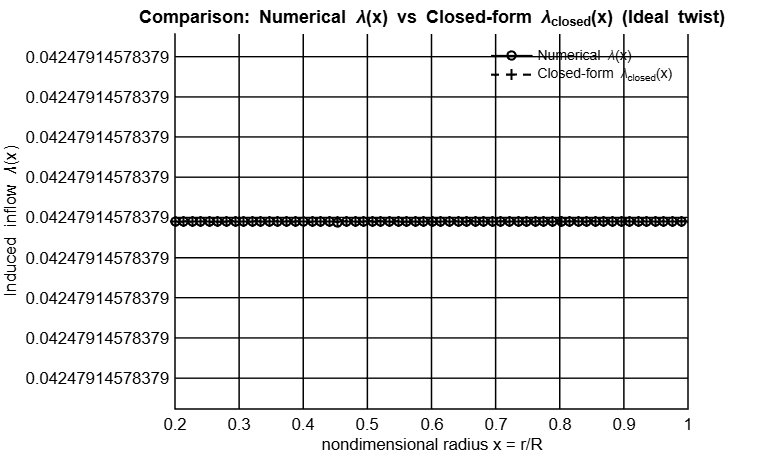

%% PLOT: theta(x) for 4 cases (degrees)
figure('Color','w','Position',[100 100 900 520]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');    % 
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);

line_styles = {'-','--','-.',':'};
lw = 3.5;  

ncases = length(cases);
if size(theta_profiles_deg,2) < ncases
    error('theta_profiles_deg must have one column per case in ''cases''.');
end

legend_entries = cell(1,ncases);
for k = 1:ncases
    ydata = theta_profiles_deg(:,k);
    ls = line_styles{mod(k-1,length(line_styles))+1};
    plot(x_plot, ydata, 'LineStyle', ls, 'Color', [0 0 0], 'LineWidth', lw, 'Marker', 'none');
    legend_entries{k} = sprintf('%s (\\theta_{tip}=%.2f^\\circ)', cases{k}, rad2deg(theta_tip_solution(k)));
end


xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('Pitch \theta(x) [deg]','FontSize',13,'Color','k');
title('Pitch distribution \theta(x) for 4 twist/taper cases (hover, T = 300 N)','FontSize',14,'Color','k');

xlim([x_root 1]);


lg = legend(legend_entries,'Location','northeast','FontSize',10);
lg.Box = 'off';
lg.Color = 'none';

try, lg.TextColor = 'k'; catch, set(lg,'TextColor','k'); end

ax = gca;
ax.LineWidth = 1.0;
grid on;

hold off;

- **The ideal and ideal-taper cases show a strong increase in pitch toward the root, while the no-twist and linear-twist cases remain flatter. **

- **Ideal twist achieves lower θ_tip because its distribution is aerodynamically efficient, matching the inflow shape.**

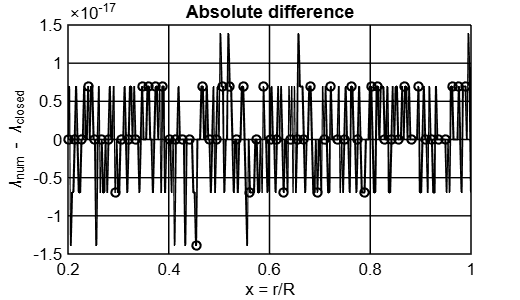

%% COMPARE: numerical lambda(x) vs closed-form lambda_closed(x) for IDEAL case

sigma_const = Nb * c_root / (pi * R);   


if exist('theta_tip_solution','var') && ismember('ideal', cases)
    try
        k_ideal = find(strcmp(cases,'ideal'),1);
        theta_tip_ideal = theta_tip_solution(k_ideal);
    catch
        theta_tip_ideal = [];
    end
else
    theta_tip_ideal = [];

end

if isempty(theta_tip_ideal)
    
    objfun_ideal = @(th) compute_total_thrust_theta(th, 'ideal') - T_req;
    try
        theta_tip_ideal = fzero(objfun_ideal, [deg2rad(2), deg2rad(40)]);
    catch
        thetas_grid = linspace(deg2rad(2), deg2rad(40), 200);
        errs = arrayfun(objfun_ideal, thetas_grid);
        [~, ind] = min(abs(errs));
        theta_guess = thetas_grid(ind);
        theta_tip_ideal = fminsearch(@(t) abs(objfun_ideal(t)), theta_guess, optimset('TolX',1e-6,'Display','off'));
    end
    fprintf('Solved theta_tip (ideal) = %.4f deg\n', rad2deg(theta_tip_ideal));
end


x_dense = linspace(x_root, 1, 300)'; 
Ndense = length(x_dense);
theta_local = zeros(Ndense,1);
lambda_num = zeros(Ndense,1);


fh_ideal = evalin('base','ideal_theta');


for i = 1:Ndense
    xi = x_dense(i);
    % local pitch (radians)
    th_i = fh_ideal(theta_tip_ideal, xi);
    theta_local(i) = th_i;
    % local chord (constant for ideal case)
    c_i = c_root;   
    sigma_i = Nb * c_i / (pi * R);

    % quadratic coefficients (same as inner loop)
    A = 4 * xi;
    B = 0.5 * sigma_i * Cl_alpha * xi;
    C = 0.5 * sigma_i * Cl_alpha * xi^2 * th_i;

    discr = B^2 + 4*A*C;
    if discr < 0
        lambda_i = 0;
    else
        lambda_i = ( -B + sqrt(discr) ) / (2*A);
        if lambda_i < 0
            lambda_i = ( -B - sqrt(discr) ) / (2*A);
        end
    end
    lambda_num(i) = lambda_i;
end

lambda_closed = (sigma_const * Cl_alpha / 16) .* ( sqrt( 1 + (32 .* (theta_local .* x_dense)) ./ (sigma_const * Cl_alpha) ) - 1 );

% Plot comparison 
lw_plot = 1.5;
Ndense = length(x_dense);
mark_every = max(1, round(Ndense/60));  
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);


plot(x_dense, lambda_num, 'k-', 'LineWidth', lw_plot, ...
    'Marker','o', 'MarkerSize',6, 'MarkerIndices',1:mark_every:Ndense, ...
    'MarkerFaceColor','none', 'MarkerEdgeColor','k', 'DisplayName','Numerical \lambda(x)');

plot(x_dense, lambda_closed, 'k--', 'LineWidth', lw_plot, ...
    'Marker','+', 'MarkerSize',8, 'MarkerIndices',1:mark_every:Ndense, ...
    'MarkerEdgeColor','k', 'DisplayName','Closed-form \lambda_{closed}(x)');


xlabel('nondimensional radius x = r/R','FontSize',12,'Color','k');
ylabel('Induced inflow \lambda(x)','FontSize',12,'Color','k');
title('Comparison: Numerical \lambda(x) vs Closed-form \lambda_{closed}(x) (Ideal twist)','FontSize',13,'Color','k');

lg = legend('Location','NorthEast','FontSize',10);
try, lg.TextColor = 'k'; catch, set(lg,'TextColor','k'); end
set(lg,'Box','off','Color','none','EdgeColor','none');

xlim([x_root 1]);
ax = gca; ax.LineWidth = 1.0;
hold off;

%Plot difference 
rel_error = (lambda_num - lambda_closed) ./ max(lambda_closed, 1e-12);
abs_diff = lambda_num - lambda_closed;

figure('Color','w','Position',[950 120 520 300]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);

plot(x_dense, abs_diff, 'k-', 'LineWidth', lw_plot, ...
    'Marker','o', 'MarkerSize',6, 'MarkerIndices',1:mark_every:Ndense, ...
    'MarkerFaceColor','none', 'MarkerEdgeColor','k');

xlabel('x = r/R','FontSize',12,'Color','k');
ylabel('\lambda_{num} - \lambda_{closed}','FontSize',12,'Color','k');
title('Absolute difference','FontSize',13,'Color','k');

xlim([x_root 1]);
ax = gca; ax.LineWidth = 1.0;
hold off;

- **The numerical λ(x) matches the closed-form solution almost exactly, confirming that the BEMT formulation and implementation are correct for ideal twist.**

### Q1 - PART - B

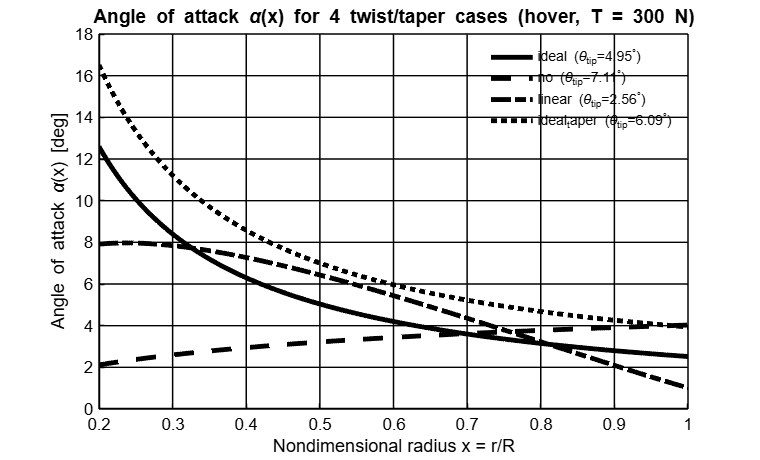

%% Variation of angle of attack alpha(x) for all 4 twist cases


cases = {'ideal','no','linear','ideal_taper'};

x_plot = linspace(evalin('base','x_root'), 1, 300)';   
Nd = length(x_plot);


Nb        = evalin('base','Nb');

R         = evalin('base','R');
Cl_alpha  = evalin('base','Cl_alpha');
rho       = evalin('base','rho');        
c_root    = evalin('base','c_root');
c_taper_f = evalin('base','c_taper');    
fh_ideal      = evalin('base','ideal_theta');
fh_no         = evalin('base','no_twist_theta');
fh_linear     = evalin('base','linear_twist_theta');
fh_ideal_taper= evalin('base','ideal_taper_theta');

% theta_tip solutions (radians)
theta_tip_solution = evalin('base','theta_tip_solution');  
if isempty(theta_tip_solution)
    error('theta_tip_solution not found in workspace. Run outer loop first.');
end


alpha_profiles_deg = zeros(Nd, length(cases));


for k = 1:length(cases)
    case_id = cases{k};
    theta_tip = theta_tip_solution(k);   % radians

    % compute theta(x) vector for this case
    switch case_id
        case 'ideal'
            theta_vec = fh_ideal(theta_tip, x_plot);            % radians
            c_vec = c_root * ones(size(x_plot));                % constant chord
        case 'no'
            theta_vec = fh_no(theta_tip, x_plot);
            c_vec = c_root * ones(size(x_plot));
        case 'linear'
            theta_vec = fh_linear(theta_tip, x_plot);
            c_vec = c_root * ones(size(x_plot));
        case 'ideal_taper'
            theta_vec = fh_ideal_taper(theta_tip, x_plot);
            c_vec = c_taper_f(x_plot);                          % tapered chord values
        otherwise
            error('Unknown case_id');
    end

    % compute local sigma(x) = Nb * c(x) / (pi * R)
    sigma_vec = Nb .* c_vec ./ (pi * R);

    % Solve quadratic pointwise for lambda(x):
    A = 4 .* x_plot;
    B = 0.5 .* sigma_vec .* Cl_alpha .* x_plot;
    C = 0.5 .* sigma_vec .* Cl_alpha .* (x_plot.^2) .* theta_vec;

    discr = B.^2 + 4 .* A .* C;
    % Guard against small negative round-off
    discr(discr < 0) = 0;

    lambda_vec = ( -B + sqrt(discr) ) ./ (2 .* A);
    neg_idx = lambda_vec < 0;
    if any(neg_idx)
        lambda_vec(neg_idx) = ( -B(neg_idx) - sqrt(discr(neg_idx)) ) ./ (2 .* A(neg_idx));
    end
    lambda_vec(lambda_vec < 0) = 0;  

    % local angle of attack alpha = theta - lambda/x  (radians)
    alpha_vec = theta_vec - (lambda_vec ./ x_plot);

    % convert to degrees for plotting
    alpha_profiles_deg(:,k) = rad2deg(alpha_vec);
end

% PLOTTING 
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);


line_styles = {'-','--','-.',':'};
lw = 3.5;

legend_entries = cell(1,length(cases));
for k = 1:length(cases)
    ydata = alpha_profiles_deg(:,k);
    ls = line_styles{mod(k-1,length(line_styles))+1};
    plot(x_plot, ydata, 'LineStyle', ls, 'Color', [0 0 0], 'LineWidth', lw, 'Marker', 'none');
    legend_entries{k} = sprintf('%s (\\theta_{tip}=%.2f^\\circ)', cases{k}, rad2deg(theta_tip_solution(k)));
end

xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('Angle of attack \alpha(x) [deg]','FontSize',13,'Color','k');
title('Angle of attack \alpha(x) for 4 twist/taper cases (hover, T = 300 N)','FontSize',14,'Color','k');

xlim([evalin('base','x_root') 1]);

lg = legend(legend_entries,'Location','northeast','FontSize',10);
lg.Box = 'off';
lg.Color = 'none';
try, lg.TextColor = 'k'; catch, set(lg,'TextColor','k'); end

ax = gca;
ax.LineWidth = 1.0;
grid on;
hold off;

- **The ideal and ideal-taper blades maintain nearly constant α(x), **

- **while no-twist and linear-twist blades show larger α near the tip, producing less uniform aerodynamic loading.**

### Q1 - PART - C

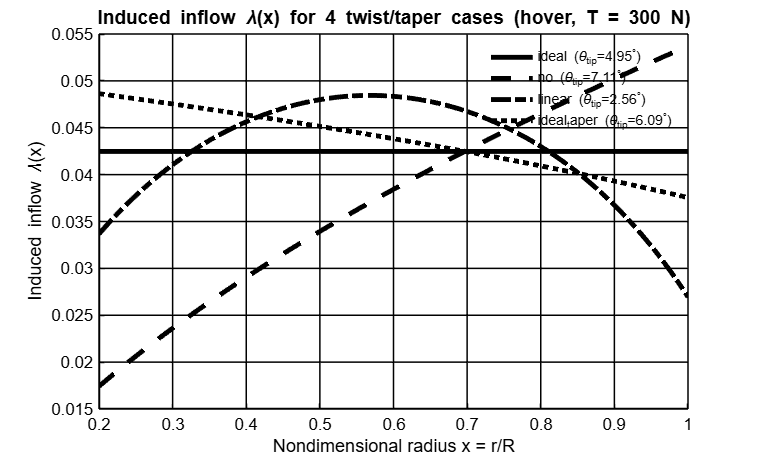

%% Variation of induced inflow lambda(x) for all 4 twist cases


cases = {'ideal','no','linear','ideal_taper'};
x_root = evalin('base','x_root');
x_plot = linspace(x_root, 1, 300)';  
Nd = length(x_plot);



Nb        = evalin('base','Nb');
R         = evalin('base','R');
Cl_alpha  = evalin('base','Cl_alpha');
c_root    = evalin('base','c_root');
c_taper_f = evalin('base','c_taper');
fh_ideal      = evalin('base','ideal_theta');
fh_no         = evalin('base','no_twist_theta');
fh_linear     = evalin('base','linear_twist_theta');
fh_ideal_taper= evalin('base','ideal_taper_theta');

theta_tip_solution = evalin('base','theta_tip_solution');
if isempty(theta_tip_solution)
    error('theta_tip_solution not found in workspace. Run outer loop first.');
end


lambda_profiles = zeros(Nd, length(cases));

% Compute lambda(x) for each case
for k = 1:length(cases)
    case_id = cases{k};
    theta_tip = theta_tip_solution(k);    % radians

    % theta(x) and chord c(x)
    switch case_id
        case 'ideal'
            theta_vec = fh_ideal(theta_tip, x_plot);
            c_vec = c_root .* ones(size(x_plot));
        case 'no'
            theta_vec = fh_no(theta_tip, x_plot);
            c_vec = c_root .* ones(size(x_plot));
        case 'linear'
            theta_vec = fh_linear(theta_tip, x_plot);
            c_vec = c_root .* ones(size(x_plot));
        case 'ideal_taper'
            theta_vec = fh_ideal_taper(theta_tip, x_plot);
            c_vec = c_taper_f(x_plot);
        otherwise
            error('Unknown case_id');
    end

    % local solidity
    sigma_vec = Nb .* c_vec ./ (pi .* R);

    A = 4 .* x_plot;
    B = 0.5 .* sigma_vec .* Cl_alpha .* x_plot;
    C = 0.5 .* sigma_vec .* Cl_alpha .* (x_plot.^2) .* theta_vec;

    discr = B.^2 + 4 .* A .* C;
    discr(discr < 0) = 0;
    lambda_vec = ( -B + sqrt(discr) ) ./ (2 .* A);
    neg_idx = lambda_vec < 0;
    if any(neg_idx)
        lambda_vec(neg_idx) = ( -B(neg_idx) - sqrt(discr(neg_idx)) ) ./ (2 .* A(neg_idx));
    end


    lambda_vec(lambda_vec < 0) = 0;

    lambda_profiles(:,k) = lambda_vec;
end

%Plot
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);

line_styles = {'-','--','-.',':'};
lw = 3.5;

legend_entries = cell(1,length(cases));
for k = 1:length(cases)
    ydata = lambda_profiles(:,k);
    ls = line_styles{mod(k-1,length(line_styles))+1};
    plot(x_plot, ydata, 'LineStyle', ls, 'Color', [0 0 0], 'LineWidth', lw, 'Marker', 'none');
    legend_entries{k} = sprintf('%s (\\theta_{tip}=%.2f^\\circ)', cases{k}, rad2deg(theta_tip_solution(k)));
end

xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('Induced inflow \lambda(x)','FontSize',13,'Color','k');
title('Induced inflow \lambda(x) for 4 twist/taper cases (hover, T = 300 N)','FontSize',14,'Color','k');

xlim([x_root 1]);

lg = legend(legend_entries,'Location','northeast','FontSize',10);
lg.Box = 'off';
lg.Color = 'none';
try, lg.TextColor = 'k'; catch, set(lg,'TextColor','k'); end

ax = gca;
ax.LineWidth = 1.0;
grid on;
hold off;

- **Ideal and ideal-taper blades exhibit smooth inflow distributions aligned with optimal loading, **

- **while no-twist and linear-twist blades show higher λ near the tip due to inefficient pitch distributions.**

### Q1 - PART - D

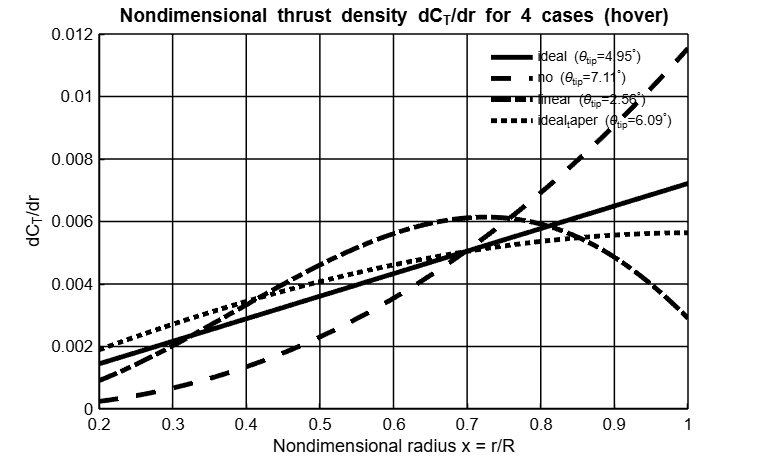

%% Thrust & Torque distributions
% Four separate figures (each with 4 curves: ideal, no, linear, ideal_taper)
% 1) dC_T/dr  (nondimensional thrust distribution)
% 2) dC_Q/dr (total torque coefficient density = dC_Qp/dr + dC_Qi/dr)
% 3) dC_Qi/dr (induced torque coefficient density)
% 4) dC_Qp/dr (profile torque coefficient density)


cases = {'ideal','no','linear','ideal_taper'};
x_root = evalin('base','x_root');
x_plot = linspace(x_root, 1, 300)';   
Nd = length(x_plot);

rho        = evalin('base','rho');
Nb         = evalin('base','Nb');
R          = evalin('base','R');
c_root     = evalin('base','c_root');
Cd0        = evalin('base','Cd0');
Cl_alpha   = evalin('base','Cl_alpha');
Omega      = evalin('base','Omega');
Aref       = evalin('base','A');           
ref_scale_T= evalin('base','ref_scale');  
ref_scale_Q= ref_scale_T * R;               


fh_ideal       = evalin('base','ideal_theta');
fh_no          = evalin('base','no_twist_theta');
fh_linear      = evalin('base','linear_twist_theta');
fh_ideal_taper = evalin('base','ideal_taper_theta');
fh_c_taper     = evalin('base','c_taper');

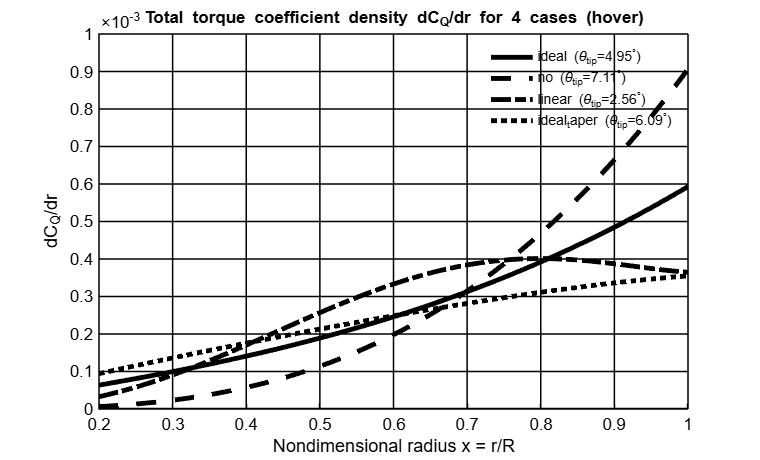



theta_tip_solution = evalin('base','theta_tip_solution');
if isempty(theta_tip_solution)
    error('theta_tip_solution not found. Run outer loop first.');
end


dCT_dr_profiles = zeros(Nd, length(cases));   
dCQp_dr_profiles = zeros(Nd, length(cases)); 
dCQi_dr_profiles = zeros(Nd, length(cases));  
dCQ_dr_profiles  = zeros(Nd, length(cases)); 


% For each case compute theta(x), chord c(x), lambda(x), f(r) = dT/dr, then torques
for k = 1:length(cases)
    case_id = cases{k};

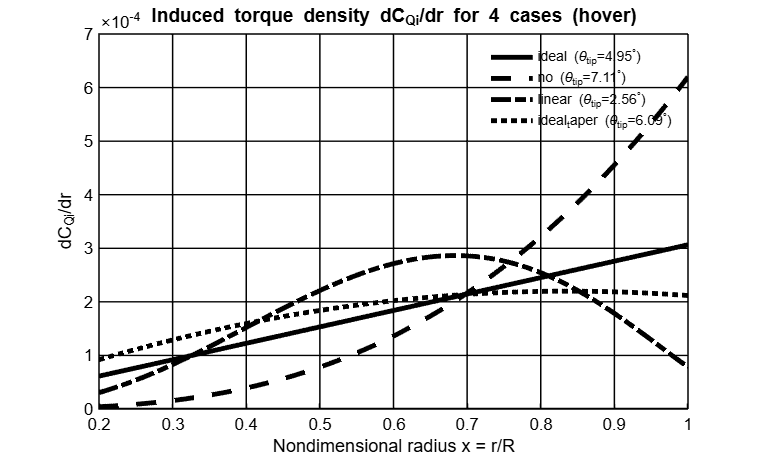

    theta_tip = theta_tip_solution(k);   % radians

    % get theta(x) and chord c(x)
    switch case_id
        case 'ideal'
            theta_vec = fh_ideal(theta_tip, x_plot);
            c_vec = c_root .* ones(size(x_plot));
        case 'no'
            theta_vec = fh_no(theta_tip, x_plot);
            c_vec = c_root .* ones(size(x_plot));
        case 'linear'
            theta_vec = fh_linear(theta_tip, x_plot);
            c_vec = c_root .* ones(size(x_plot));
        case 'ideal_taper'
            theta_vec = fh_ideal_taper(theta_tip, x_plot);
            c_vec = fh_c_taper(x_plot);
        otherwise

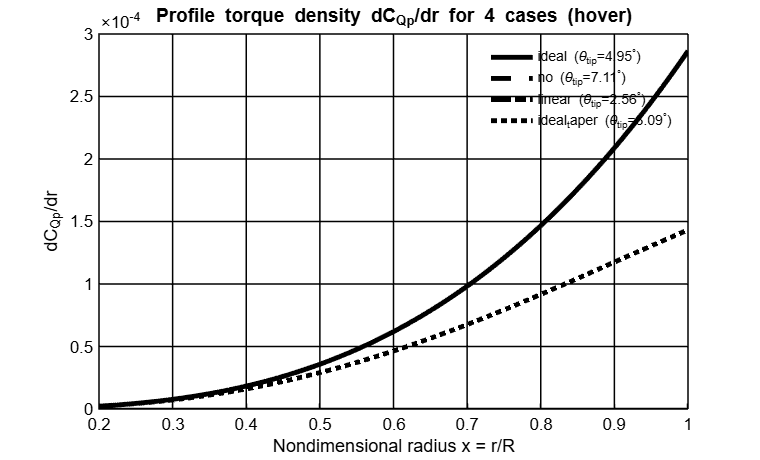

            error('Unknown case_id');
    end

    % local dimensional radius
    r_vec = x_plot .* R;

    % local solidity
    sigma_vec = Nb .* c_vec ./ (pi .* R);

    % quadratic coefficients
    A = 4 .* x_plot;
    B = 0.5 .* sigma_vec .* Cl_alpha .* x_plot;
    C = 0.5 .* sigma_vec .* Cl_alpha .* (x_plot.^2) .* theta_vec;

    discr = B.^2 + 4 .* A .* C;
    discr(discr < 0) = 0; 


    lambda_vec = ( -B + sqrt(discr) ) ./ (2 .* A);

    neg_idx = lambda_vec < 0;
    if any(neg_idx)
        lambda_vec(neg_idx) = ( -B(neg_idx) - sqrt(discr(neg_idx)) ) ./ (2 .* A(neg_idx));
    end
    lambda_vec(lambda_vec < 0) = 0;

    % local Cl
    Cl_vec = Cl_alpha .* ( theta_vec - (lambda_vec ./ x_plot) );

    % local thrust integrand (dimensional) f(r) = dT/dr
    f_r = 0.5 .* rho .* Nb .* (Omega .* r_vec).^2 .* c_vec .* Cl_vec;   % N/m

    dCT_dr_profiles(:,k) = f_r ./ ref_scale_T;

    % PROFILE torque density (dimensional): dQp/dr = r * dD/dr
    dD_dr = 0.5 .* rho .* Nb .* (Omega .* r_vec).^2 .* c_vec .* Cd0;   % N/m (drag per m)
    dQp_dr = r_vec .* dD_dr;    % N*m / m  (dimensional torque density)
    dCQp_dr_profiles(:,k) = dQp_dr ./ ref_scale_Q;  % nondim

    % INDUCED torque density (dimensional): from induced power element
    dQi_dr = f_r .* lambda_vec .* R; 
    dCQi_dr_profiles(:,k) = dQi_dr ./ ref_scale_Q;   % nondim

    % total torque coefficient density
    dCQ_dr_profiles(:,k) = dCQp_dr_profiles(:,k) + dCQi_dr_profiles(:,k);
end

% plotting helper
plot_bw = @(x,y,ls) plot(x, y, 'LineStyle', ls, 'Color', [0 0 0], 'LineWidth', 3.5, 'Marker','none');

line_styles = {'-','--','-.',':'};
legend_entries = cell(1,length(cases));


% 1) dC_T/dr (nondimensional thrust density)
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);
for k = 1:length(cases)
    ls = line_styles{mod(k-1,length(line_styles))+1};
    plot_bw(x_plot, dCT_dr_profiles(:,k), ls);
    legend_entries{k} = sprintf('%s (\\theta_{tip}=%.2f^\\circ)', cases{k}, rad2deg(theta_tip_solution(k)));
end
xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('dC_T/dr','FontSize',13,'Color','k');
title('Nondimensional thrust density dC_T/dr for 4 cases (hover)','FontSize',14,'Color','k');
xlim([x_root 1]);
lg = legend(legend_entries,'Location','northeast','FontSize',10); lg.Box='off'; lg.Color='none'; try, lg.TextColor='k'; catch, set(lg,'TextColor','k'); end
ax = gca; ax.LineWidth = 1.0; grid on; hold off;

- **Thrust Distribution dC_T/dr: *****Ideal and taper blades produce nearly elliptical thrust loading, while no-twist and linear-twist generate flatter or tip-biased thrust profiles.***


% 2) total torque coefficient density dC_Q/dr
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);
for k = 1:length(cases)
    ls = line_styles{mod(k-1,length(line_styles))+1};
    plot_bw(x_plot, dCQ_dr_profiles(:,k), ls);
end
xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('dC_Q/dr','FontSize',13,'Color','k');
title('Total torque coefficient density dC_Q/dr for 4 cases (hover)','FontSize',12,'Color','k');
xlim([x_root 1]);
lg = legend(legend_entries,'Location','northeast','FontSize',10); lg.Box='off'; lg.Color='none'; try, lg.TextColor='k'; catch, set(lg,'TextColor','k'); end
ax = gca; ax.LineWidth = 1.0; grid on; hold off;

- **Total Torque dC_Q/dr: *****The ideal and tapered cases require the least torque for the same thrust, showing better aerodynamic efficiency; no-twist produces the highest torque demand.***


% 3) induced torque coefficient density dC_Qi/dr
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);
for k = 1:length(cases)
    ls = line_styles{mod(k-1,length(line_styles))+1};
    plot_bw(x_plot, dCQi_dr_profiles(:,k), ls);
end
xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('dC_{Qi}/dr','FontSize',13,'Color','k');
title('Induced torque density dC_{Qi}/dr for 4 cases (hover)','FontSize',14,'Color','k');
xlim([x_root 1]);
lg = legend(legend_entries,'Location','northeast','FontSize',10); lg.Box='off'; lg.Color='none'; try, lg.TextColor='k'; catch, set(lg,'TextColor','k'); end
ax = gca; ax.LineWidth = 1.0; grid on; hold off;

- **Induced Torque dC_Qi/dr: *****Induced torque is lowest for ideal and taper blades due to balanced inflow and α distributions, while no-twist increases induced losses near the tip.***


% 4) profile torque coefficient density dC_Qp/dr
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;

Q2: theta75 (no-twist) with Prandtl tip-loss = 6.8452 deg


set(gcf,'InvertHardcopy','off');

Q1: theta (no-twist) without tip-loss     = 7.1065 deg


set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);

Difference (deg) = -0.2613 deg


set(gca,'GridColor','k','GridAlpha',1);
for k = 1:length(cases)
    ls = line_styles{mod(k-1,length(line_styles))+1};
    plot_bw(x_plot, dCQp_dr_profiles(:,k), ls);
end
xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('dC_{Qp}/dr','FontSize',13,'Color','k');
title('Profile torque density dC_{Qp}/dr for 4 cases (hover)','FontSize',14,'Color','k');
xlim([x_root 1]);
lg = legend(legend_entries,'Location','northeast','FontSize',10); lg.Box='off'; lg.Color='none'; try, lg.TextColor='k'; catch, set(lg,'TextColor','k'); end
ax = gca; ax.LineWidth = 1.0; grid on; hold off;

- **Profile Torque dC_Qp/dr: *****Profile torque remains similar in shape for all cases but is slightly higher for non-ideal twist profiles because they operate at higher α and Cl.***

## Q2. 

For the above problem, implement Prandtl's tip-loss function using the numerical technique discussed in class. For the "no blade" twist case, find out the reference pitch input θ_75 needed for hovering flight. Compare the result with that from Q1. Show the effect of the tip-loss on the induced inflow, thrust distribution, and total torque distribution with non-dimensional radial location on separate plots. Discuss your results.

## Solution:

### Algorithm Used for Solving Q2: (Using Similar Concept as Q1)

- Implements **Prandtl’s tip-loss function** iteratively at each radius (closed-form λ with F factor, then compute F from φ, iterate to convergence), using exact formula as in class:


$$\lambda \left(x\right)=\frac{\sigma \;c_{l\alpha } }{16}\;\left\lbrack \sqrt{1+\frac{32\;F\ldotp \theta \ldotp x}{\sigma \;c_{l\alpha } }}-1\right\rbrack$$


Where F is,


$$F=\left(\frac{2}{\pi }\right)\cos^{-1} \left(e^{-f} \right)$$


Here f is,


$$f=\frac{N_b }{2}\left\lbrack \frac{1-x}{\mathrm{xsin}\left(\phi \right)}\right\rbrack$$


- Uses the **six-point Gaussian quadrature inner loop** (same element partition as Q1) when computing total thrust inside the outer root finder.

- Finds the **reference pitch θ75** (for the *no-twist* case) that gives **T = 300 N** with tip loss, and compares it to the no-tip result from Q1.

%% Q2: Prandtl tip-loss for "no" twist case (θ75 reference)


% numeric constants from Q1
rho        = evalin('base','rho');
Nb         = evalin('base','Nb');
R          = evalin('base','R');
c_root     = evalin('base','c_root');
Cd0        = evalin('base','Cd0');
Cl_alpha   = evalin('base','Cl_alpha');
Omega      = evalin('base','Omega');
T_req      = evalin('base','T_req');
x_root     = evalin('base','x_root');

% integration / Gauss data & element edges
r_edges    = evalin('base','r_edges');
y_gauss    = evalin('base','y_gauss');
w_gauss    = evalin('base','w_gauss');
M          = evalin('base','M');

% other helpers 
ref_scale_T = evalin('base','ref_scale');  
Aref        = evalin('base','A');           
ref_scale_Q = ref_scale_T * R;              


fh_no      = evalin('base','no_twist_theta');
fh_c_of_x  = evalin('base','c_of_x');   

% Q1 solution for 'no' case (theta tip / theta75 from Q1)
theta_no_Q1_vec = evalin('base','theta_tip_solution');  % all cases vector
cases_list = {'ideal','no','linear','ideal_taper'};
k_no = find(strcmp(cases_list,'no'),1);
if isempty(k_no)
    error('Cannot find ''no'' case index in workspace ''cases''. Ensure Q1 outer loop was run.');
end
theta_no_Q1 = theta_no_Q1_vec(k_no);   % radians 


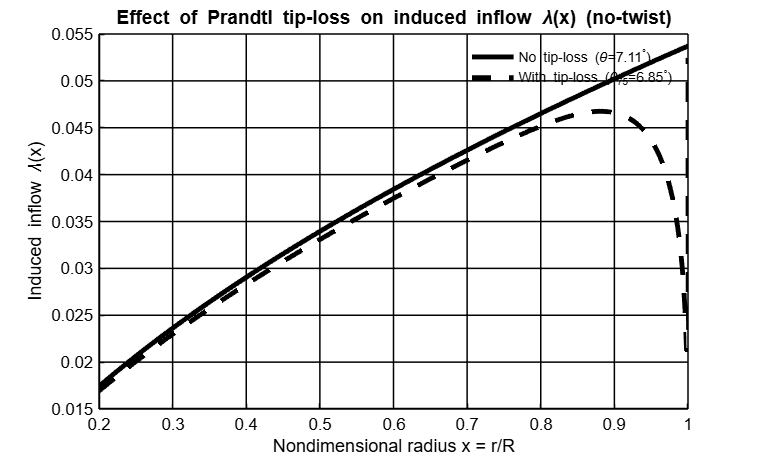

%iterative lambda-with-tiploss at a point

function lambda_ret = lambda_with_tiploss_point_scalar(theta_local, x_local, sigma_local, Nb_local, Cl_alpha_local)
   
    tol = 1e-8;
    maxit = 200;

    denom = sigma_local * Cl_alpha_local;
    if denom <= 0
        lambda_old = 0;
    else
        arg0 = 1 + (32 * 1.0 .* (theta_local .* x_local)) ./ denom;
        arg0 = max(arg0, 1.0);
        lambda_old = (denom/16) * ( sqrt(arg0) - 1 );
    end

    for it = 1:maxit
        % compute phi
        if x_local <= 0
            phi = pi/2;
        else
            phi = atan2(lambda_old, x_local);
        end
        sphi = sin(phi);
        if abs(sphi) < 1e-10
            fval = Inf;
        else
            fval = (Nb_local/2) * ( (1 - x_local) / ( x_local * sphi ) );
        end

        if isinf(fval) && fval>0
            expnegf = 0;
        else
            expnegf = exp(-fval);
            expnegf = min(max(expnegf, 0), 1);
        end

        % compute F
        acos_arg = expnegf;
        acos_arg = min(max(acos_arg, -1), 1);
        F = (2/pi) * acos(acos_arg);

        % new lambda
        if denom <= 0
            lambda_new = 0;
        else
            arg2 = 1 + (32 * F .* (theta_local .* x_local)) ./ denom;

            arg2 = max(arg2, 1.0);
            lambda_new = (denom/16) * ( sqrt(arg2) - 1 );
        end

        if abs(lambda_new - lambda_old) < tol
            lambda_ret = lambda_new;
            return;
        end
        lambda_old = lambda_new;
    end

    lambda_ret = lambda_old;
end



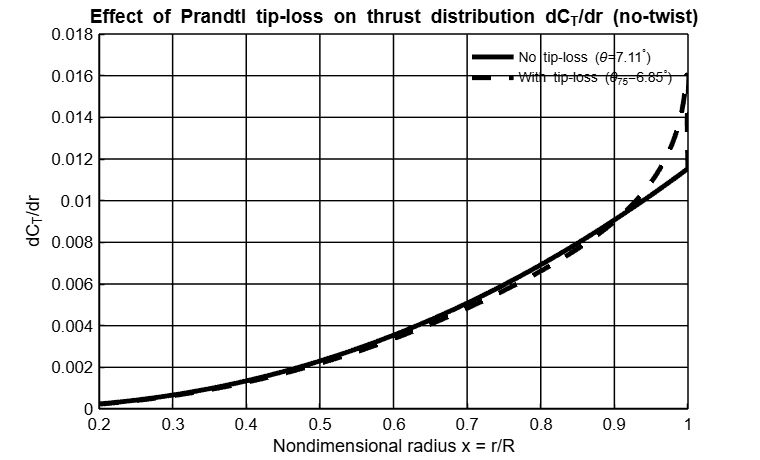

% Inner-loop: total thrust using Gauss-6 but with tip-loss lambdas ----


function T_total = compute_total_thrust_theta_tiploss(theta_ref, case_id)
    R_ws       = evalin('base','R');

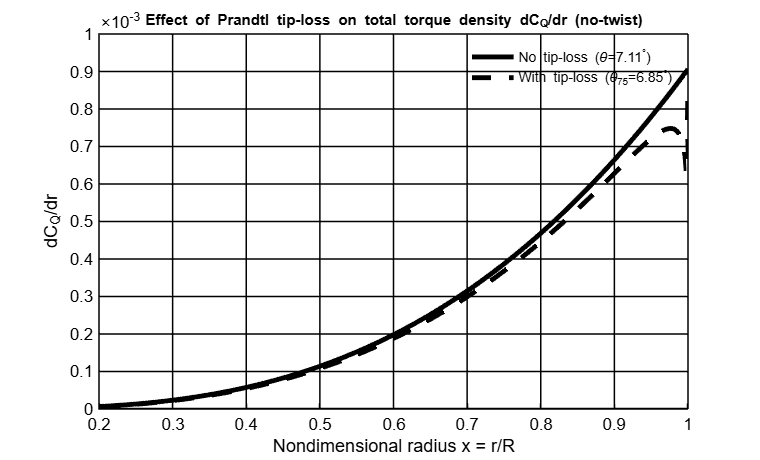

    Nb_ws      = evalin('base','Nb');
    Omega_ws   = evalin('base','Omega');
    Cl_alpha_ws= evalin('base','Cl_alpha');
    rho_ws     = evalin('base','rho');
    r_edges_ws = evalin('base','r_edges');
    y_gauss_ws = evalin('base','y_gauss');
    w_gauss_ws = evalin('base','w_gauss');
    M_ws       = evalin('base','M');
    c_root_ws  = evalin('base','c_root');

    T_total = 0.0;

    for k = 1:M_ws
        a_k = r_edges_ws(k);
        b_k = r_edges_ws(k+1);
        elem_sum = 0.0;
        half_len = (b_k - a_k) / 2;
        mid_pt = (b_k + a_k) / 2;

        for j = 1:length(y_gauss_ws)

            yj = y_gauss_ws(j);
            wj = w_gauss_ws(j);

            r_j = half_len * yj + mid_pt;
            x_j = r_j / R_ws;

            if strcmp(case_id,'no')
                theta_j = theta_ref;
                c_j = c_root_ws;
            else
                theta_j = theta_ref;
                c_j = c_root_ws;
            end

            sigma_j = Nb_ws * c_j / (pi * R_ws);

            
            lambda_j = lambda_with_tiploss_point_scalar(theta_j, x_j, sigma_j, Nb_ws, Cl_alpha_ws);

            % local Cl
            Cl_j = Cl_alpha_ws * ( theta_j - (lambda_j / x_j) );

            % thrust integrand
            f_rj = 0.5 * rho_ws * Nb_ws * (Omega_ws * r_j)^2 * c_j * Cl_j;

            elem_sum = elem_sum + wj * f_rj;
        end

        Element_Thrust = elem_sum * half_len;
        T_total = T_total + Element_Thrust;
    end
end



% solve outer loop for theta75 with tip-loss 
objfun_tiploss = @(th) compute_total_thrust_theta_tiploss(th, 'no') - T_req;

theta_lo = deg2rad(0.5);   % lower bound
theta_hi = deg2rad(60);    % upper bound 
opts = optimset('TolX',1e-6,'Display','off');

try
    theta75_tiploss = fzero(objfun_tiploss, [theta_lo theta_hi], opts);
catch
    thetas_grid = linspace(theta_lo, theta_hi, 300);
    errs = arrayfun(objfun_tiploss, thetas_grid);
    [~, ind] = min(abs(errs));
    theta_guess = thetas_grid(ind);
    theta75_tiploss = fminsearch(@(t) abs(objfun_tiploss(t)), theta_guess, optimset('TolX',1e-6,'Display','off'));
end


fprintf('Q2: theta75 (no-twist) with Prandtl tip-loss = %.4f deg\n', rad2deg(theta75_tiploss));
fprintf('Q1: theta (no-twist) without tip-loss     = %.4f deg\n', rad2deg(theta_no_Q1));
fprintf('Difference (deg) = %.4f deg\n', rad2deg(theta75_tiploss - theta_no_Q1));

%  compute lambda, thrust, torque densities
x_dense = linspace(x_root, 1, 400)'; 
Ndense = length(x_dense);

lambda_no = zeros(Ndense,1);
lambda_tiploss = zeros(Ndense,1);
dCT_dr_no = zeros(Ndense,1);
dCT_dr_tiploss = zeros(Ndense,1);
dCQ_dr_no = zeros(Ndense,1);   
dCQ_dr_tiploss = zeros(Ndense,1);

% compute no-tip case pointwise
for i = 1:Ndense
    xi = x_dense(i);
    % no-tip: theta is constant
    theta_local_no = theta_no_Q1;
    % chord
    c_i = c_root;
    sigma_i = Nb * c_i / (pi * R);

    % Solve quadratic as in Q1 inner loop to get lambda_no
    A = 4 * xi;
    B = 0.5 * sigma_i * Cl_alpha * xi;
    C = 0.5 * sigma_i * Cl_alpha * xi^2 * theta_local_no;
    discr = B^2 + 4*A*C;
    if discr < 0
        lam_no = 0;
    else
        lam_no = (-B + sqrt(discr)) / (2*A);
        if lam_no < 0
            lam_no = (-B - sqrt(discr)) / (2*A);
        end
    end
    lambda_no(i) = max(0, lam_no);

    % local Cl, f_r (dimensional), dC_T/dr (nondim)
    Cl_i_no = Cl_alpha * (theta_local_no - (lambda_no(i)/xi));
    r_i = xi * R;
    f_r_no = 0.5 * rho * Nb * (Omega * r_i)^2 * c_i * Cl_i_no;   % N/m
    dCT_dr_no(i) = f_r_no / ref_scale_T;

    % torques: profile drag + induced torque density
    dD_dr_no = 0.5 * rho * Nb * (Omega * r_i)^2 * c_i * Cd0;    % N/m
    dQp_dr_no = r_i * dD_dr_no;
    dQi_dr_no = f_r_no * lambda_no(i) * R;
    dCQ_dr_no(i) = (dQp_dr_no + dQi_dr_no) / ref_scale_Q;
end

% compute tip-loss case pointwise (and theta75_tiploss)
for i = 1:Ndense
    xi = x_dense(i);
    theta_local_tl = theta75_tiploss; 
    c_i = c_root;
    sigma_i = Nb * c_i / (pi * R);

    % find lambda with tip-loss
    lam_tl = lambda_with_tiploss_point_scalar(theta_local_tl, xi, sigma_i, Nb, Cl_alpha);
    lambda_tiploss(i) = max(0, lam_tl);

    % local Cl and thrust integrand and q's
    r_i = xi * R;
    Cl_i_tl = Cl_alpha * (theta_local_tl - (lambda_tiploss(i)/xi));
    f_r_tl = 0.5 * rho * Nb * (Omega * r_i)^2 * c_i * Cl_i_tl;
    dCT_dr_tiploss(i) = f_r_tl / ref_scale_T;

    % torques
    dD_dr_tl = 0.5 * rho * Nb * (Omega * r_i)^2 * c_i * Cd0;
    dQp_dr_tl = r_i * dD_dr_tl;
    dQi_dr_tl = f_r_tl * lambda_tiploss(i) * R;
    dCQ_dr_tiploss(i) = (dQp_dr_tl + dQi_dr_tl) / ref_scale_Q;
end


% PLOTTING
line_styles = {'-','--'};   
lw = 3.5;

% 1) Induced inflow lambda(x)
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);

plot(x_dense, lambda_no, 'LineStyle', line_styles{1}, 'Color',[0 0 0], 'LineWidth', lw);
plot(x_dense, lambda_tiploss, 'LineStyle', line_styles{2}, 'Color',[0 0 0], 'LineWidth', lw);

xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('Induced inflow \lambda(x)','FontSize',13,'Color','k');
title('Effect of Prandtl tip-loss on induced inflow \lambda(x) (no-twist)','FontSize',14,'Color','k');
xlim([x_root 1]);
legend({sprintf('No tip-loss (\\theta=%.2f^\\circ)', rad2deg(theta_no_Q1)), ...
        sprintf('With tip-loss (\\theta_{75}=%.2f^\\circ)', rad2deg(theta75_tiploss))}, ...
        'Location','northeast','FontSize',10,'Box','off','Color','none');
try, legend('TextColor','k'); catch, set(legend,'TextColor','k'); end
ax = gca; ax.LineWidth = 1.0; grid on; hold off;

- **λ(x): *****Tip-loss reduces induced inflow near the outer span, causing λ(x) to drop close to the tip.***


% 2) Thrust distribution dC_T/dr
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);

plot(x_dense, dCT_dr_no, 'LineStyle', line_styles{1}, 'Color',[0 0 0], 'LineWidth', lw);
plot(x_dense, dCT_dr_tiploss, 'LineStyle', line_styles{2}, 'Color',[0 0 0], 'LineWidth', lw);

xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('dC_T/dr','FontSize',13,'Color','k');
title('Effect of Prandtl tip-loss on thrust distribution dC_T/dr (no-twist)','FontSize',14,'Color','k');
xlim([x_root 1]);
legend({sprintf('No tip-loss (\\theta=%.2f^\\circ)', rad2deg(theta_no_Q1)), ...
        sprintf('With tip-loss (\\theta_{75}=%.2f^\\circ)', rad2deg(theta75_tiploss))}, ...
        'Location','northeast','FontSize',10,'Box','off','Color','none');
try, legend('TextColor','k'); catch, set(legend,'TextColor','k'); end
ax = gca; ax.LineWidth = 1.0; grid on; hold off;

- **dC_T/dr: *****Thrust near the tip decreases due to vortex roll-up, requiring a higher θ₇₅ to recover total thrust.***


% 3) Total torque density dC_Q/dr
figure('Color','w','Position',[150 120 760 460]); clf; hold on; grid on;
set(gcf,'InvertHardcopy','off');
set(gca,'Color','w','XColor','k','YColor','k','FontSize',12);
set(gca,'GridColor','k','GridAlpha',1);

plot(x_dense, dCQ_dr_no, 'LineStyle', line_styles{1}, 'Color',[0 0 0], 'LineWidth', lw);
plot(x_dense, dCQ_dr_tiploss, 'LineStyle', line_styles{2}, 'Color',[0 0 0], 'LineWidth', lw);

xlabel('Nondimensional radius x = r/R','FontSize',13,'Color','k');
ylabel('dC_Q/dr','FontSize',13,'Color','k');
title('Effect of Prandtl tip-loss on total torque density dC_Q/dr (no-twist)','FontSize',11,'Color','k');
xlim([x_root 1]);
legend({sprintf('No tip-loss (\\theta=%.2f^\\circ)', rad2deg(theta_no_Q1)), ...
        sprintf('With tip-loss (\\theta_{75}=%.2f^\\circ)', rad2deg(theta75_tiploss))}, ...
        'Location','northeast','FontSize',10,'Box','off','Color','none');
try, legend('TextColor','k'); catch, set(legend,'TextColor','k'); end
ax = gca; ax.LineWidth = 1.0; grid on; hold off;

- **dC_Q/dr: *****Total torque slightly increases because the rotor must operate at a higher pitch to compensate for tip-loss.***